- Lab 5a. Download the training datasets from one of the two  pT-range folders.  In each folder, there are 2 files, each containing 100k jets. The signal dataset is labeled as “higgs” and the background dataset is labeled as  “qcd.”

- Lab 5b. Explore the training data by addressing following questions:

- Do all features provide discrimination power between signal and background? 

- Are there correlations among these features? 

- Compute expected discovery sensitivity by normalizing each sample appropriately. 

- Develop a plan to optimize the discovery sensitivity by applying selections to these features. 

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

data_index = 1;

qcd_data_labels = ["qcd_100000_pt_250_500", "qcd_100000_pt_1000_1200"];
higgs_data_labels = ["higgs_100000_pt_250_500", "higgs_100000_pt_1000_1200"];

qcd_label = qcd_data_labels(data_index);
higgs_label = higgs_data_labels(data_index);

h5disp("data/" + qcd_label +".h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("data/" + higgs_label +".h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd_data = h5read("data/" + qcd_label+".h5", ['/' convertStringsToChars(qcd_label)]);
higgs_data = h5read("data/" + higgs_label +".h5",['/' convertStringsToChars(higgs_label)]);

% puts in form so first index is for each data point, second is for each
% quantity measured
qcd_data = qcd_data';
higgs_data = higgs_data';


## 0. "Book report" on the data

Below, we will be working with simulated LHC data. The data that we are given is not raw simulation information, which originally includes a full simulation of every particle collision and interaction with the LHC detector, but 14 variables that are constructed from that data. Specifically, they are 14 variables calculated for "jets" that are generated during the colision. In general, when we collide the 2 protons together at very high energies, this can generate very heavy particles. These particles quickly decay, and due to the large difference in mass between the initial heavy particles (including the higgs we are looking for) and the decay products, the initial heavy particles are highly boosted (have lots of momentum in the lab frame). As a consequence, as the initial heavy particles have large momentum, their decay products end up being highly collimated to conserve the 4 momentum as they decay. This leads to single proton-proton collisions which generate single heavy particles ending up with a scattering of many particles by the time they reach the detector. This cluster of collimated particles that originated from a single proton-proton collision is called a jet.

Now the raw information that is collected in real life (and simulated in the full simulation) is just where the different detectors in the LHC detect individual particles, and what their momentum is. Because of the wide variety of particles that are generated, some with charge some without, some with lots of mass some with none, some moving faster than other, there are several different kinds of detectors that are used simulataneously to collect information from as many particles as possible. But as I mentioned, the detector gets hit for each particle. And what we really care about is the information from all the particles that came from a single decay. As a consequence, a lot of time and effort has gone into figuring out how to best group the individual particle detections into appropriate jets. This is all upstream from the data that we are examining. We have been given data, 100k points for each data set, that correspond to already labeled jets. I will not be delving further into how the jets are labeled for now, as there are a variety of techniques. 

So, we have 100k jets labeled. We have grouped the individual particle detections already, now what? Well, again people have worked hard looking for the best ways to label and identify jets. So we are given the data for 14 different variables that describe the jet. I will break them down below.

pt: 

eta:

phi:

mass:

ee2:

ee3:

d2:

angularity:

t1:

t2:

t3:

t21: 

t32:

KtDeltaR:

All of this is well and good, but can be essentially ignored. That is to say, we could have been given the two data sets and told the 14 quantities were "A-ness" through "N-ness" and we just needed to figure out how to identify if a future sample given included objects from both data sets or just from one. These 14 quantities were already chosen for their usefullness in identifying jets. They have already been thought about, at length, by many people as physically motivated important aspects of the jet structure. So when looking at how to use the data, we can take some of the physical descriptions of these quantities as sanity checks for our correlations or our ability to use them to discriminate between the two populations, but I will be operating under the assumption that they were chosen well. 

## 1. Do all features provide discrimination power between signal and background? 

To examine how the different aspect of the data might be able to discriminate between the Higgs signal and the background, we will examine histograms of each of the 14 types of data for both data sets. Then, we will examine the ratio of the higgs data to the qcd data in the range of the higgs data and plot a ratio of the higgs signal to the background signal over that same range. Histogram bins that have some Higgs signal but no background are set to 0: the idea being that these 100k samples might be insufficient to see how many background events are there. Even if there were supposed to be on average 2 events in that histogram box from the background, there is still a 13% chance of having none. Including those bins thus has a risk of us being over confident in our detection, so we throw them out. We find that not all of the 14 jet variables are good for discriminating between the two populations. Looking at the histogram of the ratio of higgs events to qcd background events, regions where that is higher provide us better discrimination. In particular, for the whole data set the ratio should be about 1/200 (discussed in section 3) so anywhere it is higher than that gives us a way to identify regions of this 14 dimensional space that have more higgs events or qcd events. This will allow us to throw out regions where most (or all) of the events are qcd events to the point that we can look at the total number of detections in that region of 14 dimensional space and compare it to just the qcd background with a significant difference. 

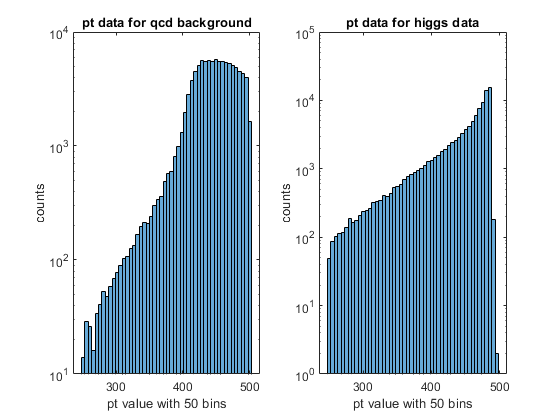

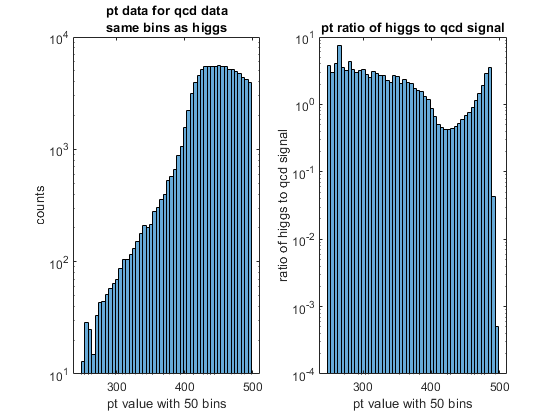

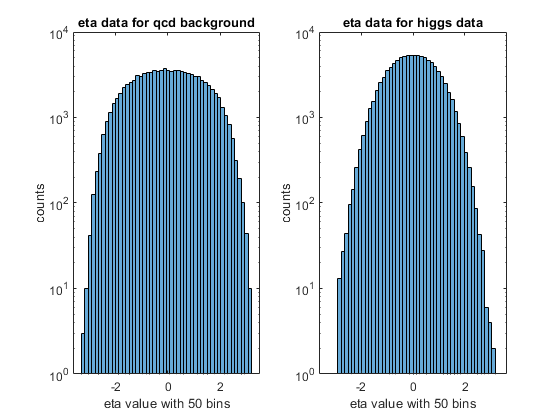

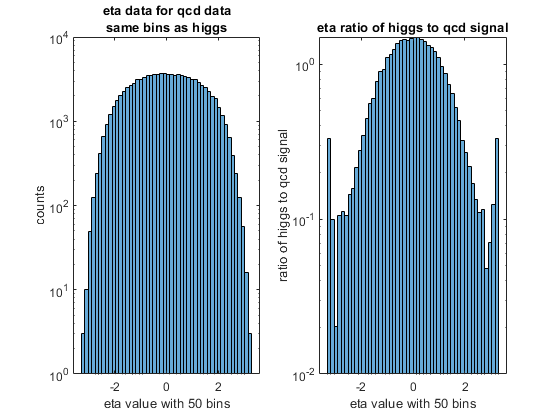

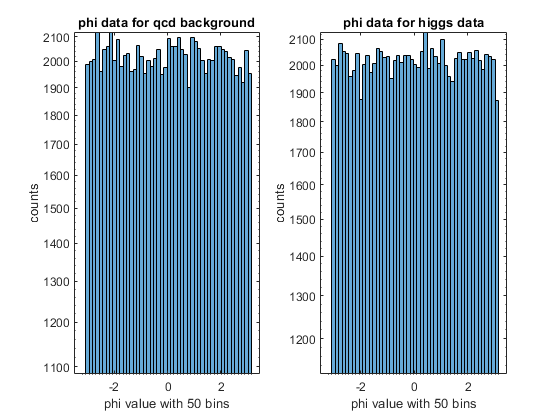

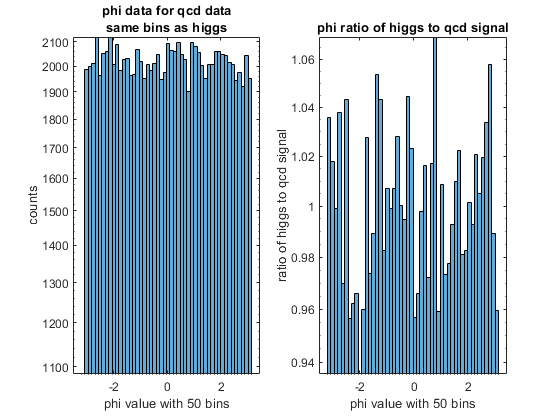

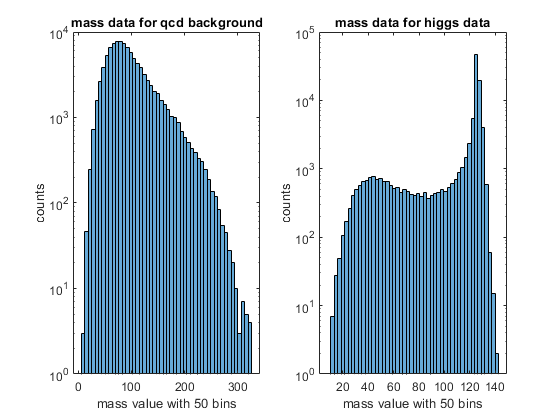

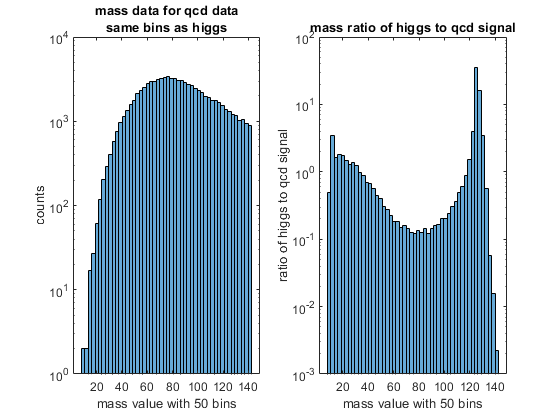




for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    figure
    
    subplot(1,2,1)
    qcd_hist = histogram(qcd_data(:, i), nbins);
    title([label ' data for qcd background'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    subplot(1,2,2)
    higgs_hist = histogram(higgs_data(:, i), nbins);
    title([label ' data for higgs data'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    figure 
    subplot(1,2,1)
    qcd_restricted_hist = histogram(qcd_data(:, i), higgs_hist.BinEdges);
    title({[label ' data for qcd data'], 'same bins as higgs'})
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    subplot(1,2,2)
    ratio_values = higgs_hist.BinCounts ./ (qcd_restricted_hist.BinCounts);
    ratio_values(isinf(ratio_values)) = 0;
    ratio_values(isnan(ratio_values)) = 0;
    ratio_hist = histogram('BinEdges', higgs_hist.BinEdges, 'BinCounts',ratio_values);
    title([label ' ratio of higgs to qcd signal'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('ratio of higgs to qcd signal')
    set(gca, 'Yscale', 'log')
    
    higgs_hist_list(i) = higgs_hist;    
    qcd_hist_list(i) = qcd_hist;
    qcd_restricted_hist_list(i) = qcd_restricted_hist;
    ratio_hist_list(i) = ratio_hist;
end

## 2. Are there correlations among these features? 

Below I plot correlations between the 14 parameters in both the higgs and qcd background datasets. As discussed in the introduction, some have correlations and some do not. In section 4 I describe how I use this (a little) to restrict the region of data appropriately.  

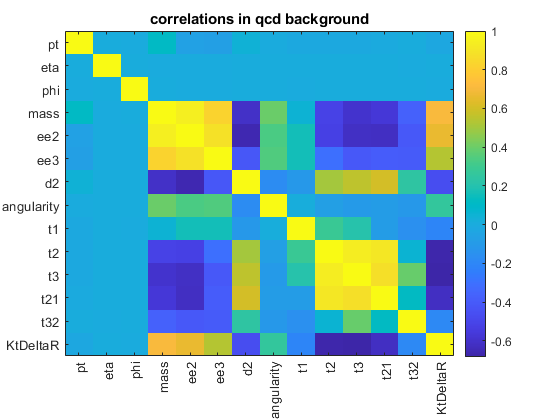

qcd_data_correlations = corrcoef(qcd_data);
higgs_data_correlations = corrcoef(higgs_data);

figure;
imagesc(qcd_data_correlations)
title('correlations in qcd background')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

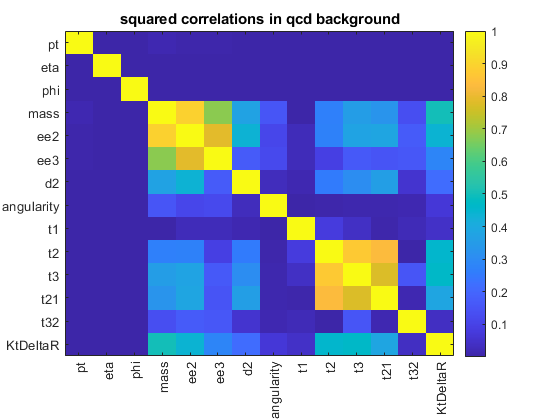


figure
imagesc(qcd_data_correlations.^2)
title('squared correlations in qcd background')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

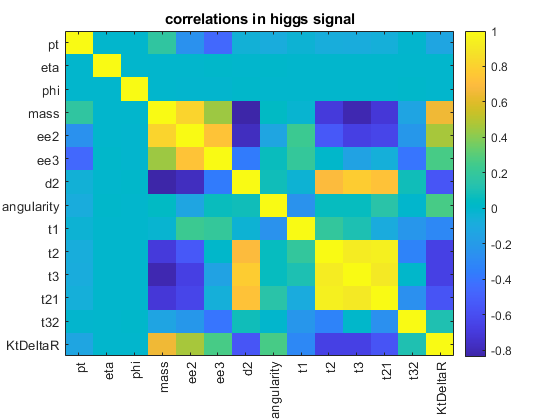


figure;
imagesc(higgs_data_correlations)
title('correlations in higgs signal')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

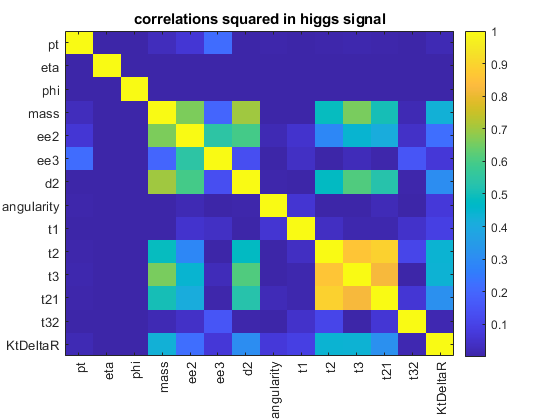

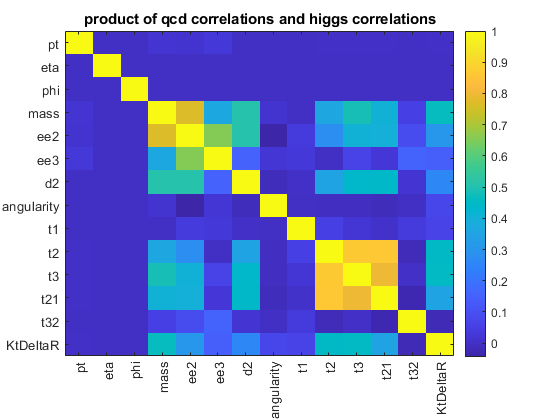


figure
imagesc(higgs_data_correlations.^2)
title('correlations squared in higgs signal')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

##  3. Compute expected discovery sensitivity by normalizing each sample appropriately.

Just looking at the raw data, before making cuts to what we include, we can examine the probability of detection. Essentially, we look at the probability of getting the expected number of counts if we include the higgs interaction compared to just the qcd background. This amounts to asking the question: what is the probability that we see $N_{higgs} + N_{qcd}$ events or more assuming that we have a background distribution that is a poisson distributed counts with a mean of $N_{qcd}$: 

n_higgs_list = [100, 50];
n_qcd_list = [20000, 2000];

n_higgs = n_higgs_list(data_index);
n_qcd = n_qcd_list(data_index);

background_prob_to_observe_total = 1- poisscdf(n_qcd + n_higgs, n_qcd)

background_prob_to_observe_total = 0.2385

## 4. Develop a plan to optimize the discovery sensitivity by applying selections to these features. 

So we can see that from just looking at counts of the full data set that the probability of observing the expected counts from background and the higgs with just the background is ~1/4. Thus, we do not expect to be able to make a discovery claim, which requires ~1/3.5 million probability of seeing counts that high from just the background. The goal is then to use the above correlation data and histogram data to select subsets of the data to do statistics on. By selecting regions of the data to look at that exclude large numbers of qcd background without excluding lots of higgs events, we should be able to reduce the probability of the full measurement. 

First I will write a function that will take in a data set, an index for what value to look at, and a list of ranges of values that then returns all of the counts that fall in those ranges. Below I give an example of a cut that, from the sample data given, would allow for 5 sigma detection. As of now, I have only included a way to restrict based on individual values, so this doesn't include cuts that incorporate more than one variable.

I start by restricting all the data to regions where the ratio of higgs to background events is 60 percent. I then fine tuned 3 parameters: mass, t32, and t3. These three seemed to have low correlations with each other while discriminating well between the higgs signal and the qcd background. In the future, I could expand the ability to appropriately restrict the data by allowing for restrictions that depend on multiple parameters. For example, 

% qcd_data 
% higgs_data

% higgs_hist_list
% qcd_hist_list
% qcd_restricted_hist_list
% ratio_hist_list
% ^ the histogram data that was plotted above

restricted_qcd = qcd_data;
restricted_higgs = higgs_data;

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

comparison_indices = 1:14;
comparison_boundaries = 0.6*ones(1, 14);
comparison_boundaries(4) = 2;
comparison_boundaries(11) = 0.5;
comparison_boundaries(13) = 0.5;


for i=1:length(comparison_indices)
    index = comparison_indices(i);
    boundary = comparison_boundaries(i);
    included_bins = find(ratio_hist_list(index).Values >=boundary);
    included_ranges = zeros(2, length(included_bins));
    
    for j = 1:length(included_bins)
        included_ranges(1, j) = ratio_hist_list(index).BinEdges(included_bins(j));
        included_ranges(2, j) = ratio_hist_list(index).BinEdges(included_bins(j)+1);
    end
    
    restricted_qcd = restrict_data(restricted_qcd, index, included_ranges);
    restricted_higgs = restrict_data(restricted_higgs, index, included_ranges);
end

qcd_data_size = size(qcd_data);
higgs_data_size = size(higgs_data);

restricted_qcd_size = size(restricted_qcd);
restricted_higgs_size = size(restricted_higgs);



fraction_qcd_kept = restricted_qcd_size(1)/qcd_data_size(1)

fraction_qcd_kept = 0.0026

fraction_higgs_kept = restricted_higgs_size(1)/higgs_data_size(1)

fraction_higgs_kept = 0.4065

nqcd = n_qcd*fraction_qcd_kept;
nhiggs = n_higgs*fraction_higgs_kept;

discovery_sensitivity = 1 - poisscdf(nqcd+nhiggs, nqcd)

discovery_sensitivity = 1.3903e-07

sensitivity_sigma = norminv(1 - discovery_sensitivity)

sensitivity_sigma = 5.1377

So here, with just some manual fine tuning, we have pretty good sensitivity and only throw out 60% percent of the true higgs signal. 

function [restricted_data] = restrict_data(data, value_index, value_range_list)
    % data: each row is a data point with each column a different quantity
    % value_index: from 1:14, indicates which column we are looking at
    % value_range_list: a (2:n) list. each (:, i) indicates a lower and
    % upper bound for a range of values that the data point can fall in
    
    values = data(:, value_index);
    size_value_range_list = size(value_range_list);
    is_included = zeros(length(values),1);
    
    for i=1:size_value_range_list(2)
        lb = value_range_list(1, i);
        ub = value_range_list(2, i);
        above_lb = values > lb;
        below_ub = values < ub;
        in_range = above_lb & below_ub;
        is_included = is_included | in_range;
    end
    
    included_indices = is_included;
    
    restricted_data = data(included_indices, :);
end

